% upright
% -------


% constants

m = 1; % kg
g = 9.8; % m / s^2
l = 0.3; % m

% initial values

J = m*l^2; % kg*m^2

b = 0.1; % damping coefficient
u = 0; % torque

% initial position

theta_0 = 0.0; % upright
theta_d_0 = 0.0;

tspan = [0 10];

x0 = [theta_0; theta_d_0];

f = @(t, x) [
    x(2);
    (m*g*l*sin(x(1)) - b*x(2) + u) / J
];

[t, x] = ode45(f, tspan, x0);

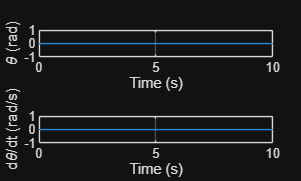

figure;

subplot(2,1,1);
plot(t, x(:,1))
xlabel('Time (s)')
ylabel('\theta (rad)')
grid on;

subplot(2,1,2)
plot(t, x(:,2))
xlabel('Time (s)');
ylabel('d\theta/dt (rad/s)');
grid on;

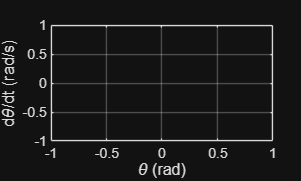

figure;
plot(x(:,1), x(:,2));
xlabel('\theta (rad)')
ylabel('d\theta/dt (rad/s)')
grid on

Pendulum remains in equilibrium in upright position

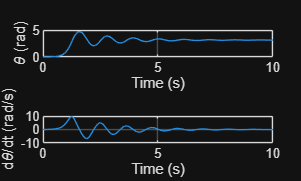

% small perturbation to theta
% ---------------------------

% constants

m = 1; % kg
g = 9.8; % m / s^2
l = 0.3; % m

% initial values

J = m*l^2; % kg*m^2

b = 0.1; % damping coefficient
u = 0; % torque

% initial position

theta_0 = 0.01; % small perturbation
theta_d_0 = 0;

tspan = [0 10];

x0 = [theta_0; theta_d_0];

f = @(t, x) [
    x(2);
    (m*g*l*sin(x(1)) - b*x(2) + u) / J
    ];

[t, x] = ode45(f, tspan, x0);

figure;

subplot(2,1,1);
plot(t, x(:,1))
xlabel('Time (s)')
ylabel('\theta (rad)')
grid on;

subplot(2,1,2)
plot(t, x(:,2))
xlabel('Time (s)');
ylabel('d\theta/dt (rad/s)');
grid on;

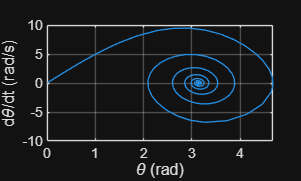


figure;
plot(x(:,1), x(:,2));
xlabel('\theta (rad)')
ylabel('d\theta/dt (rad/s)')
grid on

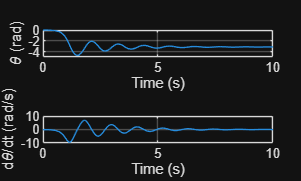

% small perturbation to d_theta
% -----------------------------

% constants

m = 1; % kg
g = 9.8; % m / s^2
l = 0.3; % m

% initial values

J = m*l^2; % kg*m^2

b = 0.1; % damping coefficient
u = 0; % torque

% initial position

theta_0 = 0.0;
theta_d_0 = -0.1; % small perturbation

tspan = [0 10];

x0 = [theta_0; theta_d_0];

f = @(t, x) [
    x(2);
    (m*g*l*sin(x(1)) - b*x(2) + u) / J
    ];

[t, x] = ode45(f, tspan, x0);

figure;

subplot(2,1,1);
plot(t, x(:,1))
xlabel('Time (s)')
ylabel('\theta (rad)')
grid on;

subplot(2,1,2)
plot(t, x(:,2))
xlabel('Time (s)');
ylabel('d\theta/dt (rad/s)');
grid on;

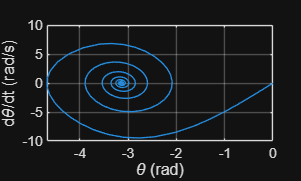


figure;
plot(x(:,1), x(:,2));
xlabel('\theta (rad)')
ylabel('d\theta/dt (rad/s)')
grid on

In both cases, theta converges to approximately +-PI, in other words pendulum travels 180 degrees from the initial upward equilibrium and ends up hanging in a vertical position, pointing downward

% discretization
% --------------


% constants

m = 1; % kg
g = 9.8; % m / s^2
l = 0.3; % m

% initial values

J = m*l^2; % kg*m^2

b = 0.1; % damping coefficient
u = 0; % torque

% initial positionthis time hanging/

theta_0 = 0.1; % small perturbation
theta_d_0 = 0.0;

% linear model

Ac = [0, 1; m*g*l/J, -b/J];
Bc = [0; 1/J];

eig(Ac)

ans =     5.1869
   -6.2980


Both eigenvalues are real, one is positive and one is negative. Therefore, the linear system is unstable. Earlier non-linear simulations confirm that a small perturbation to the pendulum causes it to move away from its position when it is facing upright

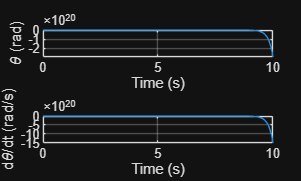

f_lin = @(t,x) Ac*x + Bc*u;

[t,x] = ode45(f_lin, tspan, x0);

figure;
subplot(2,1,1)
plot(t, x(:,1))
xlabel('Time (s)')
ylabel('\theta (rad)')
grid on

subplot(2,1,2)
plot(t, x(:,2))
xlabel('Time (s)')
ylabel('d\theta/dt (rad/s)')
grid on

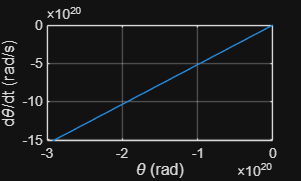


figure;
plot(x(:,1), x(:,2));
xlabel('\theta (rad)')
ylabel('d\theta/dt (rad/s)')
grid on

% discrete model

ts = 0.01; % sampling period

C = eye(2);
D = zeros(2, 1);

ss_model = ss(Ac, Bc, C, D);
res = c2d(ss_model, ts, 'zoh');

Ac

Ac =          0    1.0000
   32.6667   -1.1111


Bc

Bc =          0
   11.1111


eig(Ac)

ans =     5.1869
   -6.2980



Ad = res.A

Ad =     1.0016    0.0100
    0.3250    0.9906


Bd = res.B

Bd =     0.0006
    0.1106


eig(Ad)

ans =     1.0532
    0.9390


Model is now discrete, so to infer stability we observe magnitude of eigenvalues relative to 1. Both are real and one is > 1, so discrete system is unstable. Plots below should confirm this

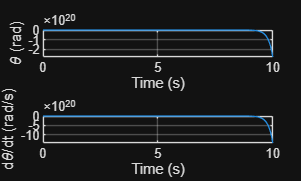

N_steps = 1000; % 10 seconds
x = zeros(2, N_steps);
x(:,1) = x0;

for k = 1:N_steps-1
    x(:,k+1) = Ad*x(:,k) + Bd*u;
end

time_axis = (0:N_steps-1)*ts;

figure;
subplot(2,1,1)
plot(time_axis, x(1,:))
xlabel('Time (s)')
ylabel('\theta (rad)')
grid on

subplot(2,1,2)
plot(time_axis, x(2,:))
xlabel('Time (s)')
ylabel('d\theta/dt (rad/s)')
grid on

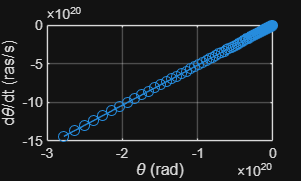


figure;
plot(x(1,:), x(2,:), '-o')
xlabel('\theta (rad)')
ylabel('d\theta/dt (ras/s)')
grid on



% LQR controller

Q = eye(2);
R = 1;

[K,S,e] = dlqr(Ad,Bd,Q,R);

K

K =     5.8213    1.2734


S

S =   479.9303   54.4627
   54.4627   12.6623


e

e =     0.9749
    0.8733



eig_closed = eig(Ad - Bd*K)

eig_closed =     0.9749
    0.8733


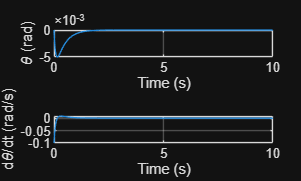


% Discrete-time LQR simulation

N_steps = 1000;

x_lqr = zeros(2,N_steps);
x_lqr(:,1) = x0;

u_lqr = zeros(1,N_steps-1);

for k = 1:N_steps-1

    u_lqr(k) = -K*x_lqr(:,k);

    x_lqr(:,k+1) = Ad*x_lqr(:,k) + Bd*u_lqr(k);

end

time_axis = (0:N_steps-1)*ts;

figure;

subplot(2,1,1)
plot(time_axis,x_lqr(1,:))
xlabel('Time (s)')
ylabel('\theta (rad)')
grid on

subplot(2,1,2)
plot(time_axis,x_lqr(2,:))
xlabel('Time (s)')
ylabel('d\theta/dt (rad/s)')
grid on

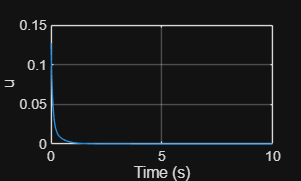


figure;

plot(time_axis(1:end-1),u_lqr)
xlabel('Time (s)')
ylabel('u')
grid on